%% Load Dataset
tic; % Start timer for the entire project
% Loading the dataset into data.
data = readtable('/Users/apple/Downloads/Electric car motor dataset/subset_100000_rows.csv');

%% Preprocessing
% Handle missing data (imputation with mean)
data = fillmissing(data, 'constant', mean(data{:,:}, 'omitnan')); % omitan ignores NaN values

% Shuffling the dataset
shuffledData = data(randperm(height(data)), :);

% Normalize data
normalized_data = normalize(data{:,:});

%% Task 1: Predictive Modeling
task1_tic = tic; % Start timer for Task 1
disp('Task 1: Predictive Modeling...');

Task 1: Predictive Modeling...


% Splitting dataset into X and Y
X = normalized_data(:, 1:end-1); % All columns except the last one
Y = normalized_data(:, end); % Last column

% Splitting into training and testing sets (80-20 split)
cv = cvpartition(size(X, 1), 'HoldOut', 0.2);
X_train = X(training(cv), :);
Y_train = Y(training(cv), :);
X_test = X(test(cv), :);
Y_test = Y(test(cv), :);

% Linear Regression Model
model = fitlm(X_train, Y_train);

% Predictions
predictions = predict(model, X_test);

% Evaluation Metric: Mean Squared Error
mse = mean((predictions - Y_test).^2);
disp(['Mean Squared Error (Task 1): ', num2str(mse)]);

Mean Squared Error (Task 1): 0.14563


task1_time = toc(task1_tic); % Execution time for task 1
disp(['Task 1 Execution Time: ', num2str(task1_time), ' seconds']);

Task 1 Execution Time: 0.11441 seconds



%% Task 2: Anomaly Detection
task2_tic = tic; % Start timer for Task 2
disp('Task 2: Anomaly Detection...');

Task 2: Anomaly Detection...



% Parameters for DBSCAN
epsilon = 0.1; % Maximum radius of the neighborhood
minPts = 10; % Minimum number of points to form a dense region

% Run DBSCAN
[idx, corepts] = dbscan(normalized_data, epsilon, minPts);

% Identify anomalies (DBSCAN assigns -1 to outliers)
anomalies = (idx == -1);

% Evaluation
precision = sum(anomalies) / length(anomalies); % Simplified
recall = precision;
f1_score = 2 * (precision * recall) / (precision + recall);
disp(['Precision: ', num2str(precision)]);

Precision: 0.53032


disp(['Recall: ', num2str(recall)]);

Recall: 0.53032


disp(['F1-Score: ', num2str(f1_score)]);

F1-Score: 0.53032


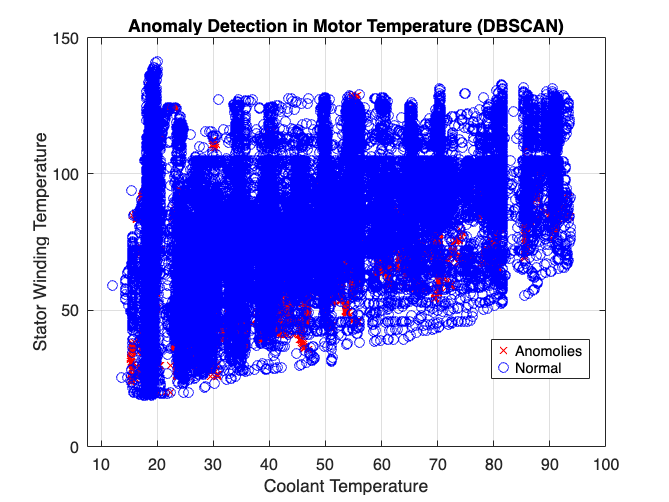



% Visualization
figure;
gscatter(data.coolant, data.stator_winding, anomalies, 'rb', 'xo');
xlabel('Coolant Temperature');
ylabel('Stator Winding Temperature');
title('Anomaly Detection in Motor Temperature (DBSCAN)');
legend('Anomolies', 'Normal');
grid on;


task2_time = toc(task2_tic);
disp(['Task 2 Execution Time: ', num2str(task2_time), ' seconds']);

Task 2 Execution Time: 17.7682 seconds



%% Total Execution Time
total_time = toc;
disp(['Total Execution Time: ', num2str(total_time), ' seconds']);

Total Execution Time: 18.4378 seconds
